# Derive and apply the rate Jacobian of a 4-dof Robotic manipulator

In this task we're going to derive and then implement the rate Jacobian for a 4-dof robotic manipulator.  The system that we're going to explore is shown below:

     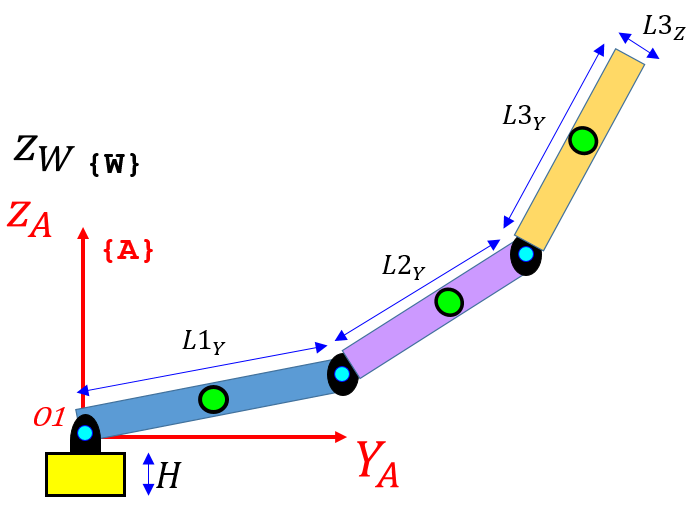   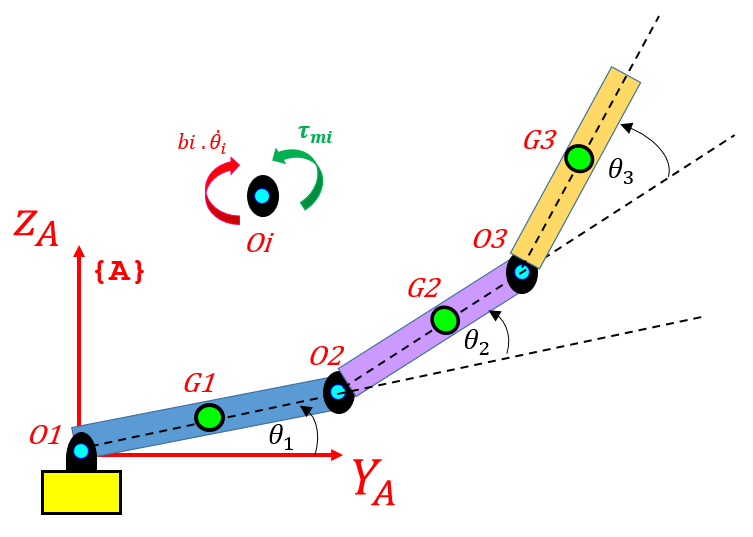   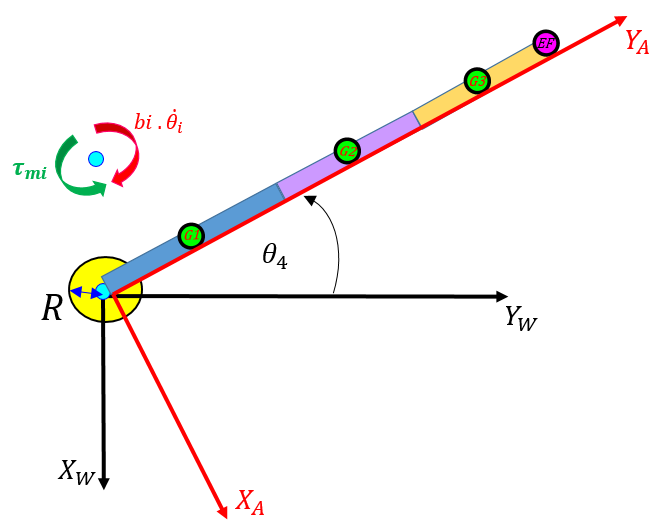

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`      

## Defining some geometry parameters:

syms   L1Y_s L2Y_s L3Y_s 

syms   theta1   
syms   theta2 
syms   theta3
syms   theta4 

## Define the X,Y position of the End effector:

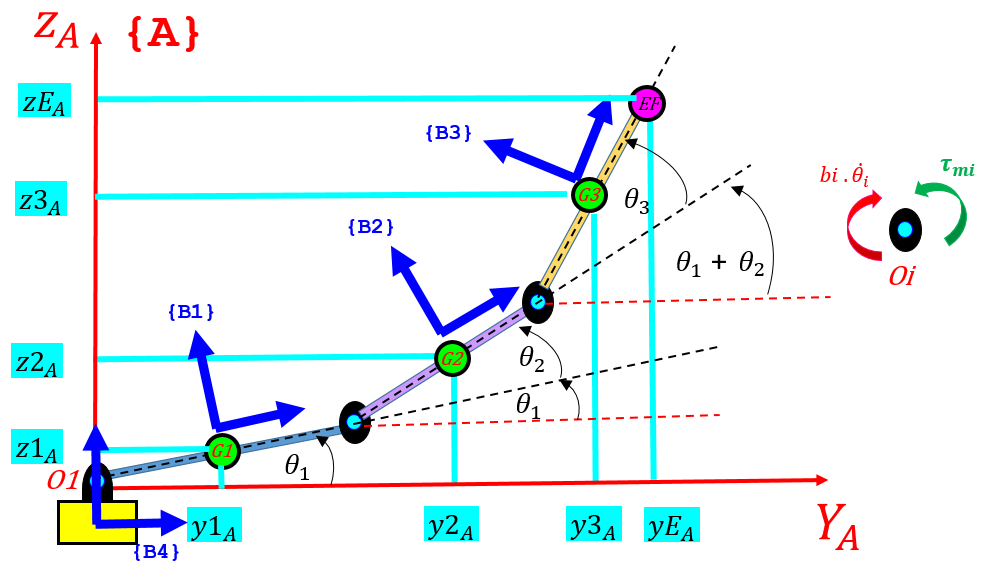     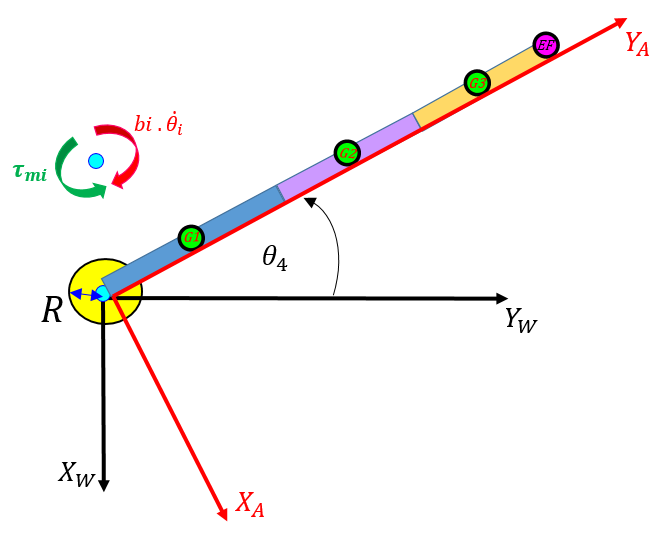

First, let's define the x,y,z position of the End Effector (EF) in terms of the {A}-Frame.  And after we've done this, we'll convert these co-ordinates into our inertial {W}-frame:

A few utility angles to help us:

alpha           = theta1 + theta2;
beta            = theta1 + theta2 + theta3;

OK: so what are the x,y,z co-ordinates of the **E****nd Effector** in components of the {A}-Frame ?

AF_pos_eff      = sym([0;0;0]);
AF_pos_eff(2,1) = L1Y_s*cos(theta1) + L2Y_s*cos(alpha) + L3Y_s*cos(beta);
AF_pos_eff(3,1) = L1Y_s*sin(theta1) + L2Y_s*sin(alpha) + L3Y_s*sin(beta);

And while we're at it, let's capture the positions of the joints and center of masses too.  Firstly here are the JOINT x,y,z positions relative to the {A}-Frame:

AF_pos_O1      = sym([0;0;0]);
AF_pos_O2      = sym([0;0;0]);
AF_pos_O3      = sym([0;0;0]);

AF_pos_O2(2,1) = L1Y_s*cos(theta1);
AF_pos_O2(3,1) = L1Y_s*sin(theta1);

AF_pos_O3(2,1) = L1Y_s*cos(theta1) + L2Y_s*cos(alpha);
AF_pos_O3(3,1) = L1Y_s*sin(theta1) + L2Y_s*sin(alpha);

And here are the link center of mass x,y,z positions relative to the {A}-Frame:

AF_pos_G1      = sym([0;0;0]);
AF_pos_G2      = sym([0;0;0]);
AF_pos_G3      = sym([0;0;0]);

AF_pos_G1(2,1) = ( L1Y_s*cos(theta1) )/2;
AF_pos_G1(3,1) = ( L1Y_s*sin(theta1) )/2;

AF_pos_G2(2,1) =   L1Y_s*cos(theta1) + ( L2Y_s*cos(alpha) )/2;
AF_pos_G2(3,1) =   L1Y_s*sin(theta1) + ( L2Y_s*sin(alpha) )/2;

AF_pos_G3(2,1) =   L1Y_s*cos(theta1) +   L2Y_s*cos(alpha) + ( L3Y_s*cos(beta) )/2;
AF_pos_G3(3,1) =   L1Y_s*sin(theta1) +   L2Y_s*sin(alpha) + ( L3Y_s*sin(beta) )/2;

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation:

   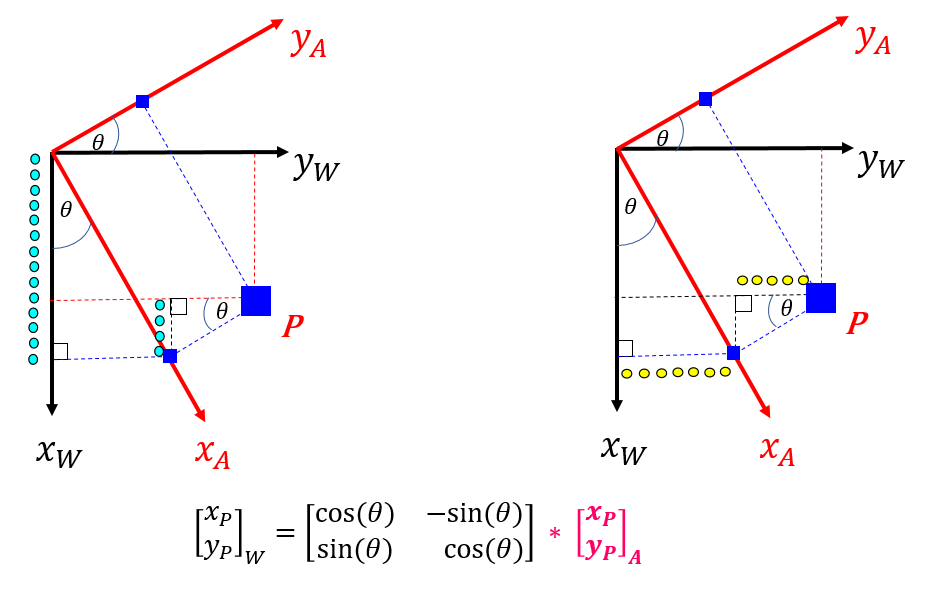

wRa = [ cos(theta4),  -sin(theta4),   0;
        sin(theta4),   cos(theta4),   0;
                  0,             0,   1 ];

So our {W}-Frame co-ordinates are:

WF_pos_eff = wRa * AF_pos_eff;    

WF_pos_O1 = wRa * AF_pos_O1;
WF_pos_O2 = wRa * AF_pos_O2;
WF_pos_O3 = wRa * AF_pos_O3;

WF_pos_G1 = wRa * AF_pos_G1;
WF_pos_G2 = wRa * AF_pos_G2;
WF_pos_G3 = wRa * AF_pos_G3;

Rip out the X,Y,Z elements for the End Effector:

the_XE_RHS = WF_pos_eff(1);
the_YE_RHS = WF_pos_eff(2);
the_ZE_RHS = WF_pos_eff(3);

And I can create a MATLAB function of these END EFFECTOR  forward kinematics:

matlabFunction([the_XE_RHS, the_YE_RHS, the_ZE_RHS], ...
    'File', 'bh_xyz_for_4dof_manip')

ans =     @bh_xyz_for_4dof_manip


## Compute our system Jacobian:

The system Jacobian is defined as:


$$J = \frac{d(X,Y,Z)}{d(\theta_1, \theta_2, \theta_3, \theta_4)} = 
\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} 
& \frac{dX}{d\theta_3}  & \frac{dX}{d\theta_4} \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} 
& \frac{dY}{d\theta_3} & \frac{dY}{d\theta_4} \cr
\frac{dZ}{d\theta_1} & \frac{dZ}{d\theta_2} 
& \frac{dZ}{d\theta_3} & \frac{dZ}{d\theta_4} \cr
}$$


the_J = jacobian( [the_XE_RHS, the_YE_RHS, the_ZE_RHS],...
                  [theta1, theta2, theta3, theta4]  )

$$the\_J = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(\theta_{4}\right)\,\sigma_{1} & \sin\left(\theta_{4}\right)\,\sigma_{2} & {\mathrm{L3Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right)\,\sigma_{3}\\ -\cos\left(\theta_{4}\right)\,\sigma_{1} & -\cos\left(\theta_{4}\right)\,\sigma_{2} & -{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right)\,\sigma_{3}\\ \sigma_{3} & {\mathrm{L2Y}}_{s}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{4} & \sigma_{4} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{L2Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}\right)+{\mathrm{L1Y}}_{s}\,\sin\left(\theta_{1}\right)+{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}={\mathrm{L2Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}\right)+{\mathrm{L3Y}}_{s}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{3}={\mathrm{L2Y}}_{s}\,\cos\left(\theta_{1}+\theta_{2}\right)+{\mathrm{L1Y}}_{s}\,\cos\left(\theta_{1}\right)+\sigma_{4}\\ \sigma_{4}={\mathrm{L3Y}}_{s}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

We can use the Jacobian in the following way:


$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt} \cr
\frac{dZ}{dt}
} = 

\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} 
& \frac{dX}{d\theta_3}  & \frac{dX}{d\theta_4}  \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} 
& \frac{dY}{d\theta_3} & \frac{dY}{d\theta_4}  \cr
\frac{dZ}{d\theta_1} & \frac{dZ}{d\theta_2} 
& \frac{dZ}{d\theta_3} & \frac{dZ}{d\theta_4}  \cr
} . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt} \cr
\frac{d\theta_4}{dt}
}$$



$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt} \cr
\frac{dZ}{dt}
} = 

J . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt} \cr
\frac{d\theta_4}{dt}
}$$


So we can then write:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt} \cr
\frac{d\theta_4}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt} \cr
\frac{dZ}{dt}
} 
\enspace \enspace \textstyle{where} \enspace J^+ \enspace \text{is the Moore-Penrose pseudoinverse of J}$$
 

We can convert the symbolic expression of the Jacobian into a MATLAB function block

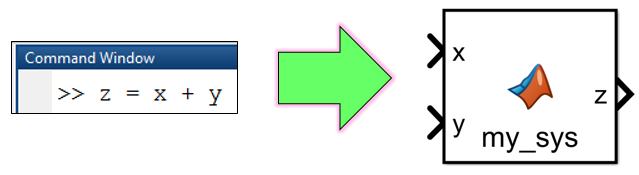

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_ikin_4dof_manip';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
                  
    % convert J into a MATLAB function block(MLF)
    matlabFunctionBlock( [MODEL_NAME,'/THE_J'], ...
                         the_J, ...
                         'Optimize', false  );
    % why not convert the FORWARD kinematic expressions 
    % into MLF blocks too !                     
    matlabFunctionBlock( [MODEL_NAME,'/THE_XEYEZE'], ...
                         the_XE_RHS, ...
                         the_YE_RHS, ...
                         the_ZE_RHS, ...
                         'Optimize', false, ...
                         'Outputs', {'XE', 'YE', 'ZE'}   ); 
    % and the W-frame O and G xy,z positions                     
    matlabFunctionBlock( [MODEL_NAME,'/THE_W_EFF_and_O_and_G'], ...
                         WF_pos_eff, ...
                         WF_pos_O1, ...
                         WF_pos_O2, ...
                         WF_pos_O3, ...   
                         WF_pos_G1, ...
                         WF_pos_G2, ...
                         WF_pos_G3, ...                            
                         'Optimize', false   );  
                     
    % and the A-frame O and G xy,z positions                     
    matlabFunctionBlock( [MODEL_NAME,'/THE_A_EFF_and_O_and_G'], ...
                         AF_pos_eff, ...
                         AF_pos_O1, ...
                         AF_pos_O2, ...
                         AF_pos_O3, ...   
                         AF_pos_G1, ...
                         AF_pos_G2, ...
                         AF_pos_G3, ...                            
                         'Optimize', false   );                           
                      
end

## Apply these concepts:

In the Simulink model `<bh_test_J_4dof_manip.slx>` we've applied the expressions that we derived earlier for the Jacobian and the FORWARD kinematics.  They look like this:

Note that the blocks above, are implementing our previouslly derived equation of:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt} \cr
\frac{d\theta_4}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt} \cr
\frac{dZ}{dt}
} 
$$


## Define some geometry parameters used by the Simulink model:

bh_parameters_for_4dof_manipulator

theta1_0     =  0;                    % rad
theta1_dot_0 =  0;                    % rad/sec 
theta2_0     =  0;                    % rad
theta2_dot_0 =  0;                    % rad/sec
theta3_0     =  0;                    % rad
theta3_dot_0 =  0;              
theta4_0     =  0;                    % rad
theta4_dot_0 =  0;      

In this model, here's what the $\dot{X}_E$ and $\dot{Y}_E$signals look like - these end effector velocities are defined in an EXCEL file called <`bh_hello_complete.xlsx`>, which we read within the Simulink model.

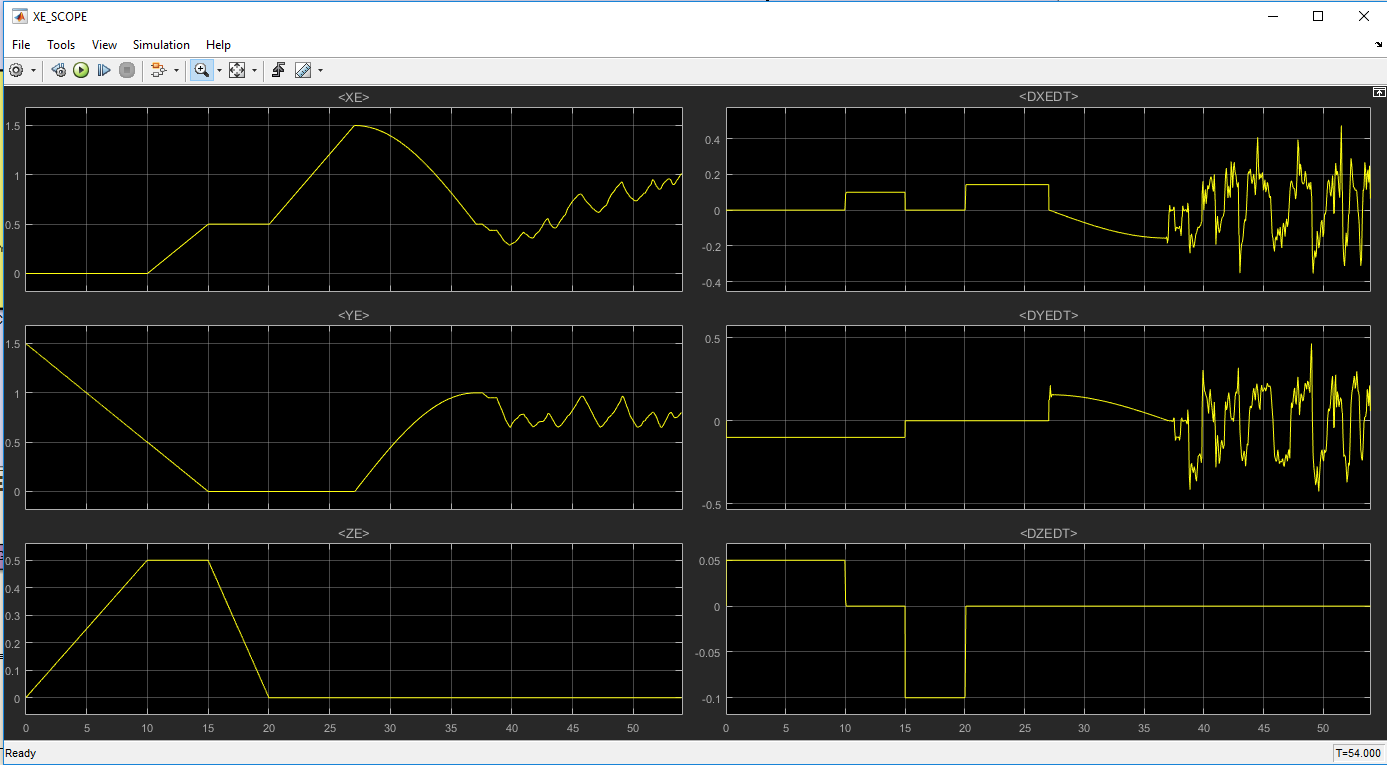

So ? - So when you plot $X_E$ with $Y_E$ you get this:

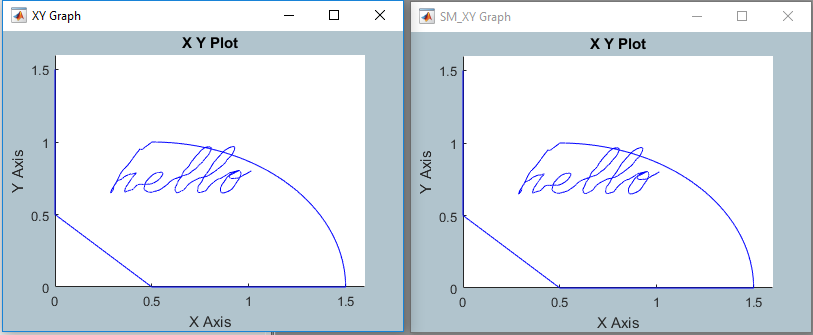

## View the kinematics:

In the same Simulink model mentioned above, I have a Simscape model that will allow you to see an animation of the 4-dof manipulator  - so check that out: